clear
M = imread('Gwanghwamun.jpg' )
whos M 


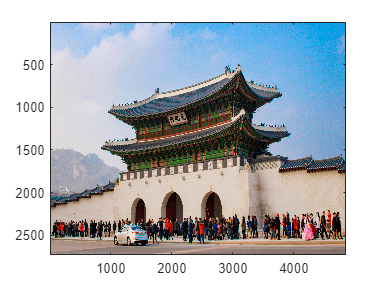

% figure; 
imagesc(M);

M = double(M);
M = sum(M, 3);
[U, S, V] = svd(M);


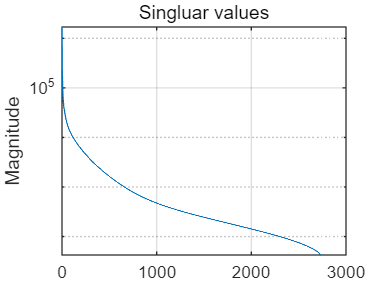

figure;
semilogy(diag(S),'LineWidth',1); % plot diagonal elements of S.
set(gca,'LineWidth',1,'FontSize',13)
title('Singluar values'); % add title
ylabel('Magnitude'); % add y-axis label 
grid on; 

MS = 4×1 cell 배열
    {2730×4855 double}
    {   0×0    double}
    {   0×0    double}
    {   0×0    double}


MS = 4×1 cell 배열
    {2730×4855 double}
    {2730×4855 double}
    {   0×0    double}
    {   0×0    double}


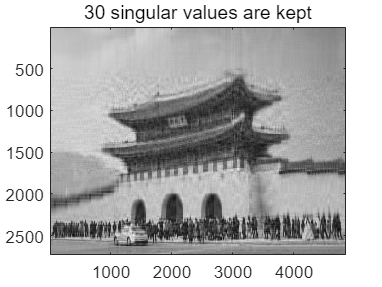

MS = 4×1 cell 배열
    {2730×4855 double}
    {2730×4855 double}
    {2730×4855 double}
    {   0×0    double}


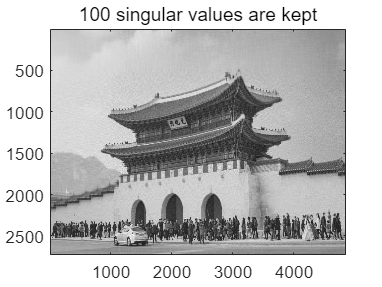

MS = 4×1 cell 배열
    {2730×4855 double}
    {2730×4855 double}
    {2730×4855 double}
    {2730×4855 double}


Nkeep = [10, 30, 100, 300];
MS = cell ( numel(Nkeep), 1);
for it = (1: numel(Nkeep))
    MS{it} = U ( :, 1:Nkeep(it))*( S ( 1:Nkeep(it),1:Nkeep(it)))*V(:, 1:Nkeep(it))'
    figure ; 
    imagesc(MS{it});
    colormap(gray);
    set(gca, 'FontSize', 13);
    title([sprintf('%i', Nkeep(it)),' singular values are kept'])
end

y = fft(M);
l = 4855

l = 4855

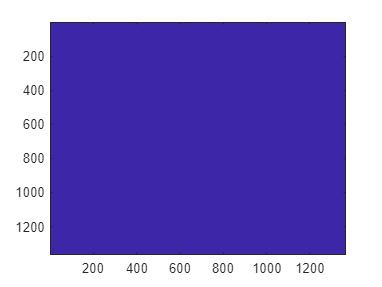

y2 = abs(y/l).^2;
%y = y2(1:2730/2+1);
%y(2:2730-1) = 2 * y(2:2730-1);
figure; 
imagesc(y2(1:l/2+1,1:l/2+1));

y

y = 1.0e+06 *

   1.5016 + 0.0000i   1.4984 + 0.0000i   1.4979 + 0.0000i   1.4972 + 0.0000i   1.4973 + 0.0000i   1.4967 + 0.0000i   1.4969 + 0.0000i   1.4975 + 0.0000i   1.4986 + 0.0000i   1.4999 + 0.0000i   1.5009 + 0.0000i   1.5026 + 0.0000i   1.5045 + 0.0000i   1.5075 + 0.0000i   1.5137 + 0.0000i   1.5200 + 0.0000i   1.5253 + 0.0000i   1.5331 + 0.0000i   1.5406 + 0.0000i   1.5461 + 0.0000i   1.5515 + 0.0000i   1.5561 + 0.0000i   1.5602 + 0.0000i   1.5616 + 0.0000i   1.5608 + 0.0000i   1.5583 + 0.0000i   1.5561 + 0.0000i   1.5550 + 0.0000i   1.5542 + 0.0000i   1.5542 + 0.0000i   1.5537 + 0.0000i   1.5537 + 0.0000i   1.5536 + 0.0000i   1.5540 + 0.0000i   1.5538 + 0.0000i   1.5530 + 0.0000i   1.5520 + 0.0000i   1.5498 + 0.0000i   1.5472 + 0.0000i   1.5445 + 0.0000i   1.5414 + 0.0000i   1.5392 + 0.0000i   1.5353 + 0.0000i   1.5291 + 0.0000i   1.5211 + 0.0000i   1.5137 + 0.0000i   1.5098 + 0.0000i   1.5079 + 0.0000i   1.5056 + 0.0000i   1.5028 + 0.0000i
  -0.0864 - 0.2153i  -0.0881 - 0.2